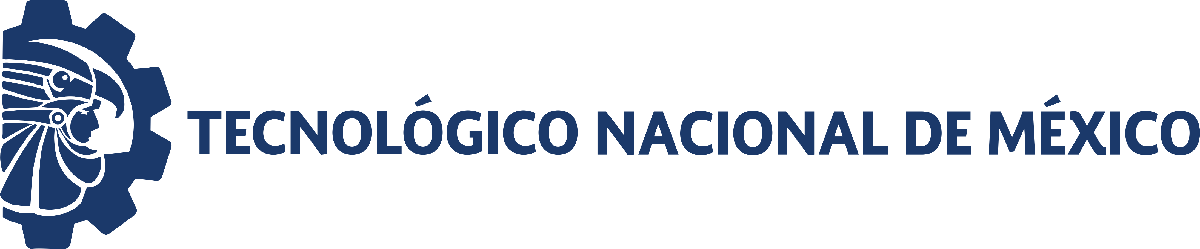                                 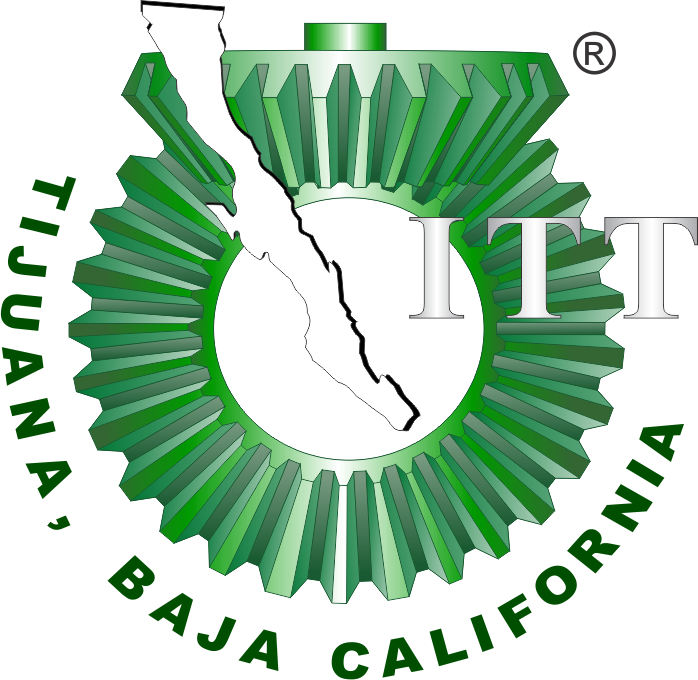

# Práctica 3: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

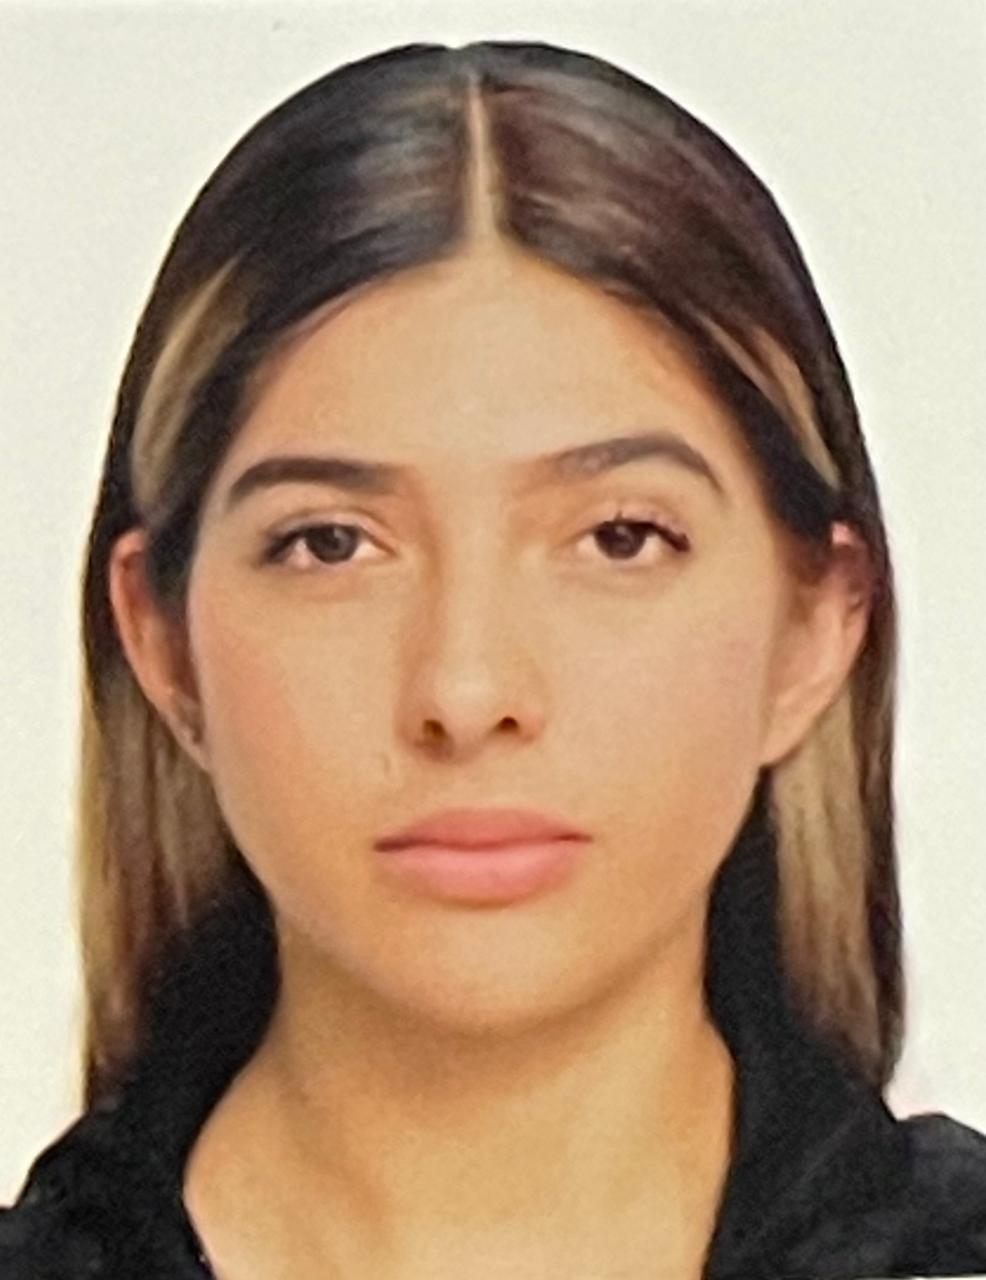

Nombre del alumno: **Gonzalez Garcia Josselin**

Número de control: **C21210380**

Correo institucional: **l21210380@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

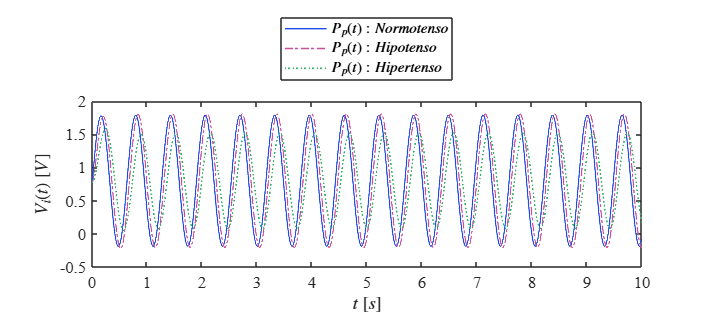

clc; clear; close all; warning('off','all')
tend = '10';
file = 'GonzalezGC21210380P3LA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim (file, parameters);
plotsignal1 (x.t, x.Ppx, x. Ppy, x.Ppz)

## Rendimiento del controlador

kP=0.00016767

kI=551.4981

kD=0

Rise time= 0.00412

Settling time=0.00733seg

Overshoot=0%

Peak=0.999

## HIPOTENSO

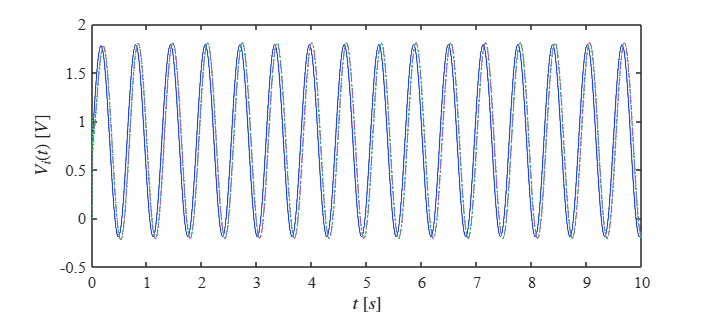

file = 'GonzalezGC21210380P3LCHIPO';
open_system(file);
x = sim (file, parameters);
opt = 'HIPOTENSO';
plotsignal (x.t, x.Ppx, x. Ppy, x.Ppz, opt)

## HIPERTENSO

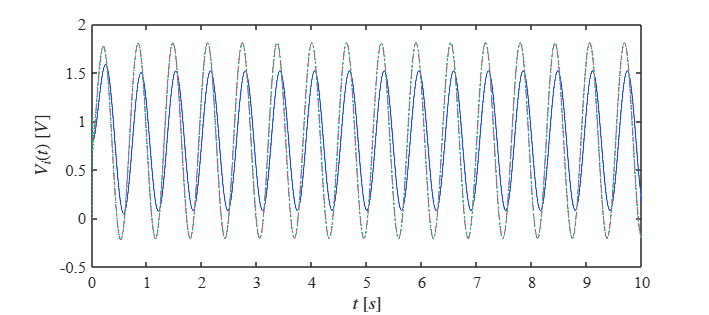

file = 'GonzalezGC21210380P3LCHIPER';
open_system(file);
x = sim (file, parameters);
opt = 'HIPERTENSO';
plotsignal (x.t, x.Ppx, x. Ppy, x.Ppz, opt)

## Funcion: Respuesta a las señales

FUNCION 1

function plotsignal(t, Ppx, Ppy, Ppz, opt)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
Azul = [0.1,0.3,0.9];
Rosa = [0.8,0.3,0.6];
Verde  = [0.2, 0.7, 0.4];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Ppx, 'timeseries'), Ppx = Ppx.Data(:); end
if isa(Ppy, 'timeseries'), Ppy = Ppy.Data(:); end
if isa(Ppz, 'timeseries'), Ppz = Ppz.Data(:); end


plot(t, Ppx, 'LineWidth', 1,'Color',Azul)
plot(t, Ppy, '-.', 'LineWidth', 1,'Color', Rosa)
plot(t, Ppz,':', 'LineWidth', 1.2,'Color', Verde)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
if opt == "Hipotenso"
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipotenso$', '$P_p(t):Tratamiento$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')

xlim([0, 10]); xticks(0:1:10)
ylim([-0.5, 2]); yticks(-0.5:0.2:2)
elseif opt == "Hipertenso"
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipertenso$', '$P_p(t):Tratamiento$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')
xlim([0, 10]); xticks(0:1:10)
ylim([-0.5, 2]); yticks(-0.5:0.2:2)
end

exportgraphics(gcf,[opt,'.pdf'], 'ContentType', 'Vector')
exportgraphics(gcf,[opt,'.png'], 'Resolution', 600);
print(opt, '-dsvg');
print(opt, '-depsc');
end


FUNCION 2

function plotsignal1(t, Ppx, Ppy, Ppz)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
Azul = [0.1,0.3,0.9];
Rosa = [0.8,0.3,0.6];
Verde  = [0.2, 0.7, 0.4];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Ppx, 'timeseries'), Ppx = Ppx.Data(:); end
if isa(Ppy, 'timeseries'), Ppy = Ppy.Data(:); end
if isa(Ppz, 'timeseries'), Ppz = Ppz.Data(:); end


plot(t, Ppx, 'LineWidth', 1,'Color',Azul)
plot(t, Ppy, '-.', 'LineWidth', 1,'Color', Rosa)
plot(t, Ppz,':', 'LineWidth', 1.2,'Color', Verde)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipotenso$', '$P_p(t):Hipertenso$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')
end